clc; clear all;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");


% Rør info
D = 8*u.mm;
D_t = 0.2*u.mm;
D_u = D;
D_i = D_u - D_t;

% Lamel info
B_kond = 36.5*u.cm;

H = 30*u.cm;
B = 6.5*u.cm;
N = 54; % antal huller
N_lam = 145;
lam_t = unitConvert(0.025*u.mm,"SI");

lam_mel = 3*u.mm;
h_lam_luft = 3*u.mm;

lam_t_tot = vpa(N_lam*lam_t,3)

$$lam\_t\_tot = 0.00362\,m$$


vpa(unitConvert(H*B,"SI"))

$$ans = 0.0195\,m^{2}$$

% Lamel areal og effektiv lamel radius
syms r_2eff

A_lam = 2*(H*B - N*pi/4 * D^2);
A_lam = vpa(unitConvert(A_lam,"SI"),4)

$$A\_lam = 0.03357\,m^{2}$$


A_lam2 = 2*N*pi*(r_2eff^2 - (D/2)^2);
A_lam2 = vpa(unitConvert(A_lam2,"SI"),4);

r_2eff_num = A_lam2 == A_lam;

r_2eff_num = solve(r_2eff_num, r_2eff);
r_2eff_num = vpa(unitConvert(r_2eff_num,"SI"),4)

$$r\_2eff\_num = \left(\begin{array}{c} -0.01072\,m\\ 0.01072\,m \end{array}\right)$$


% Lufteksponeret areal af rør
A_b = (B_kond - lam_t_tot) * D * N;
A_b = vpa(unitConvert(A_b, "SI"), 3)

$$A\_b = 0.156\,m^{2}$$


% Total overfladeareal af finner
A_t = N_lam*A_lam + A_b;
A_t = vpa(A_t, 5)

$$A\_t = 5.024\,m^{2}$$


A_lam*N_lam/A_b

$$ans = 31.181332518017945757817527890341$$

% Luftstrømshastighed
rho_luft = CP.PropsSI("D","T",273.15 + 55,"P",101325,"air") %* u.kg/u.m^3;% Luft ved 61.5C, fordi luften er 20 og r134 er 90 - filmtemp

rho_luft = 1.0758

A_1 = unitConvert(((H-1*u.cm)/2)^2*pi,"SI");
A_3 = unitConvert(H*B_kond,"SI");
A_2 = unitConvert(lam_mel * h_lam_luft * N_lam,"SI"); % mellemrummet mellem hver lamel, snævreste tværsnit luften kommer gennem, antal lameller
vpa(rho_luft,5)

$$ans = 1.0758$$

%V_1 = 1*u.m/u.s;

syms V_2 V_1
V_3 = 8.8*u.km/u.h;
V_3 = vpa(unitConvert(V_3,"SI","Derived"),4)

$$V\_3 = 2.444\,\frac{m}{s}$$


V_3 = linspace(0.1, 10);

for i = 1:length(V_3)
eq1 = separateUnits(rho_luft*A_1*V_1);
eq2 = separateUnits(rho_luft*A_2*V_2);
eq3 = separateUnits(rho_luft*A_3*V_3(i));

eq_c1 = eq1 == eq3;
eq_c2 = eq2 == eq3;

c = solve([eq_c1,eq_c2], [V_1,V_2]);
c_1 = vpa(c.V_1, 5);
c_2(i) = vpa(c.V_2, 5);

qm_luft(i) = vpa(rho_luft*separateUnits(A_3)*V_3(i),5);

end



% Varmeovergangstal for luftsiden
lambda_luft = vpa(CP.PropsSI("L","T",273.15 + 61.5,"P",101325,"air"),4)

$$lambda\_luft = 0.02891$$

dyn_vis_luft = vpa(CP.PropsSI("V","T",273.15 + 61.5,"P",101325,"air"),7)

$$dyn\_vis\_luft = 0.00002016811$$

kin_vis_luft = vpa(dyn_vis_luft/rho_luft,5)

$$kin\_vis\_luft = 0.000018747$$


C = 0.38 % 5 stk forsatte

C = 0.3800


syms alpha_f

D = unitConvert(D,"SI")

$$D = \frac{1}{125}\,m$$


Nu = alpha_f*separateUnits(D)/lambda_luft;



Re = vpa(c_2*separateUnits(D)/kin_vis_luft, 3);

for j = 1:length(Re)
Nu2 = C*Re(j)^(0.6)*(separateUnits(A_lam)/separateUnits(A_b))^-0.15;

alpha_f_eq = Nu == Nu2;

alpha_luft_num(j) = solve(alpha_f_eq, alpha_f);


end



lambda_finne = 229 %* u.W/(u.m*u.K);

lambda_finne = 229


m = sqrt((2*alpha_luft_num/(lambda_finne * separateUnits(lam_t))));
m = vpa(unitConvert(m, "SI"), 4);

r_1 = vpa(unitConvert(D/2,"SI"), 5);
r_1 = separateUnits(r_1)

$$r\_1 = 0.0039999999999995594635038287378848$$


r_2 = vpa(r_2eff_num(2), 5);
r_2 = separateUnits(r_2)

$$r\_2 = 0.010721251637638024594811926141478$$


C_2 = (2*r_1./m)/(r_2^2 - r_1^2);
C_2 = vpa(unitConvert(C_2, "SI"), 3);



eta_f = C_2.*(besselk(1, m.*r_1).*besseli(1, m.*r_2) - besseli(1, m.*r_1).*besselk(1, m.*r_2))./(besseli(0, m.*r_1).*besselk(1, m.*r_2) + besselk(0, m.*r_1).*besseli(1, m.*r_2));
eta_f = vpa(unitConvert(eta_f, "SI"), 5)

$$eta\_f = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0.37209 & 0.29603 & 0.25774 & 0.23336 & 0.21599 & 0.20276 & 0.19221 & 0.18353 & 0.1762 & 0.16991 & 0.16442 & 0.15958 & 0.15525 & 0.15135 & 0.14782 & 0.1446 & 0.14164 & 0.1389 & 0.13637 & 0.13401 & 0.13181 & 0.12975 & 0.12781 & 0.12598 & 0.12425 & 0.12262 & 0.12107 & 0.11959 & 0.11819 & 0.11685 & 0.11556 & 0.11434 & 0.11316 & 0.11203 & 0.11095 & 0.10991 & 0.10891 & 0.10794 & 0.107 & 0.1061 & 0.10523 & 0.10439 & 0.10357 & 0.10278 & 0.10201 & 0.10127 & 0.10055 & 0.099846 & 0.099163 & 0.0985 & 0.097854 & 0.097225 & 0.096612 & 0.096014 & 0.095432 & 0.094863 & 0.094309 & 0.093767 & 0.093238 & 0.09272 & 0.092215 & 0.09172 & 0.091236 & 0.090762 & 0.090299 & 0.089844 & 0.089399 & 0.088963 & 0.088536 & 0.088117 & 0.087705 & 0.087302 & 0.086906 & 0.086517 & 0.086136 & 0.085761 & 0.085393 & 0.085031 & 0.084675 & 0.084326 & 0.083982 & 0.083644 & 0.083311 & 0.082984 & 0.082662 & 0.082346 & 0.082034 & 0.081727 & 0.081424 & 0.081126 & 0.080833 & 0.080544 & 0.080259 & 0.079978 & 0.079701 & 0.079428 & 0.079159 & 0.078894 & 0.078632 & 0.078373 \end{array}\right)$$



% Overordnet lamelvirkningsgrad

eta_lamel_total = 1 - (N_lam*A_lam/A_t)*(1 - eta_f);
eta_lamel_total = vpa(eta_lamel_total, 4)

$$eta\_lamel\_total = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0.3916 & 0.3179 & 0.2808 & 0.2572 & 0.2404 & 0.2275 & 0.2173 & 0.2089 & 0.2018 & 0.1957 & 0.1904 & 0.1857 & 0.1815 & 0.1777 & 0.1743 & 0.1712 & 0.1683 & 0.1657 & 0.1632 & 0.1609 & 0.1588 & 0.1568 & 0.1549 & 0.1531 & 0.1515 & 0.1499 & 0.1484 & 0.1469 & 0.1456 & 0.1443 & 0.143 & 0.1419 & 0.1407 & 0.1396 & 0.1386 & 0.1376 & 0.1366 & 0.1357 & 0.1348 & 0.1339 & 0.133 & 0.1322 & 0.1314 & 0.1307 & 0.1299 & 0.1292 & 0.1285 & 0.1278 & 0.1272 & 0.1265 & 0.1259 & 0.1253 & 0.1247 & 0.1241 & 0.1235 & 0.123 & 0.1225 & 0.1219 & 0.1214 & 0.1209 & 0.1204 & 0.1199 & 0.1195 & 0.119 & 0.1186 & 0.1181 & 0.1177 & 0.1173 & 0.1169 & 0.1165 & 0.1161 & 0.1157 & 0.1153 & 0.1149 & 0.1145 & 0.1142 & 0.1138 & 0.1135 & 0.1131 & 0.1128 & 0.1124 & 0.1121 & 0.1118 & 0.1115 & 0.1112 & 0.1109 & 0.1106 & 0.1103 & 0.11 & 0.1097 & 0.1094 & 0.1091 & 0.1088 & 0.1086 & 0.1083 & 0.108 & 0.1078 & 0.1075 & 0.1073 & 0.107 \end{array}\right)$$

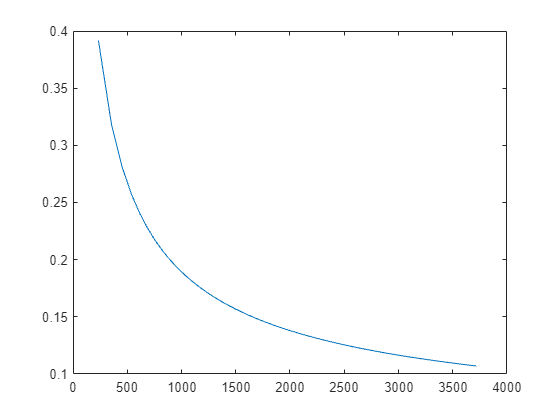

figure
plot(alpha_luft_num,eta_lamel_total)

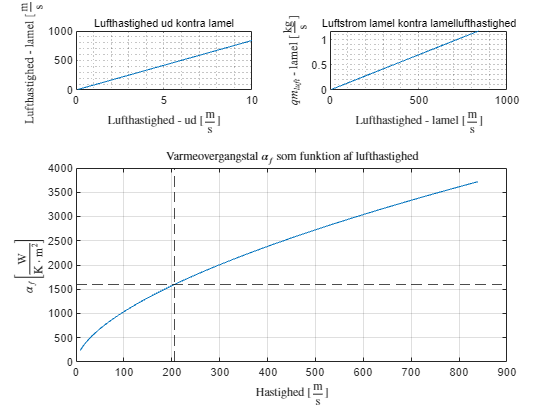

figure

tiledlayout(3,2)

nexttile
plot(V_3,c_2)
grid("minor")

title("Lufthastighed ud kontra lamel","FontSize",8,"FontWeight","normal")
ylabel("Lufthastighed - lamel [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")
xlabel("Lufthastighed - ud [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")

nexttile
plot(c_2,qm_luft)
grid("minor")

title("Luftstrom lamel kontra lamellufthastighed","FontSize",8,"FontWeight","normal")
ylabel("$qm_{luft}$ - lamel [$\frac{\mathrm{kg}}{\mathrm{s}}$]", "Interpreter","latex")
xlabel("Lufthastighed - lamel [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")


nexttile([2, 2])
plot(c_2, alpha_luft_num)
xline(205.11,"k--")
yline(1596.51,"k--")

grid("on")
title("Varmeovergangstal $\alpha_f$ som funktion af lufthastighed", "Interpreter","latex")
xlabel("Hastighed [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")
ylabel("$\alpha_f \left[\frac{\mathrm{W}}{\mathrm{K\cdot m^2}}\right]$", "Interpreter","latex")

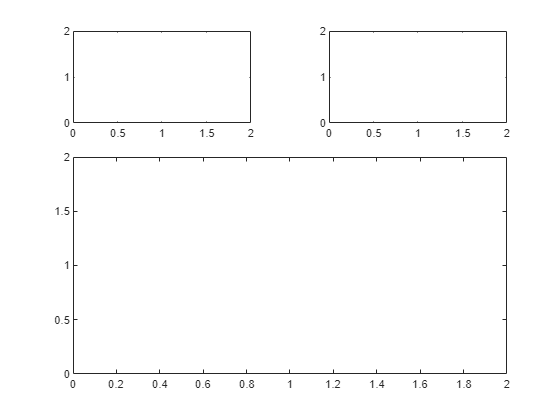


% % Varmeovergangstal for luftsiden
% lambda_luft = vpa(CP.PropsSI("L","T",273.15 + 61.5,"P",101325,"air"),4)
% dyn_vis_luft = vpa(CP.PropsSI("V","T",273.15 + 61.5,"P",101325,"air"),7)
% kin_vis_luft = vpa(dyn_vis_luft/rho_luft,5)
% 
% C = 0.38 % 5 stk forsatte
% 
% syms alpha_f
% 
% D = unitConvert(D,"SI")
% 
% Nu = alpha_f*separateUnits(D)/lambda_luft;
% 
% 
% 
% Re = vpa(205.11*separateUnits(D)/kin_vis_luft, 3);
% 
% 
% Nu2 = C*Re^(0.6)*(separateUnits(A_lam)/separateUnits(A_b))^-0.15;
% 
% alpha_f_eq = Nu == Nu2;
% 
% alpha_luft_num = solve(alpha_f_eq, alpha_f)

figure

tiledlayout(3,2)
nexttile
plot(1,1)
nexttile
plot(1,1)
nexttile([2 2])
plot(1,1)